# EX. 1. 

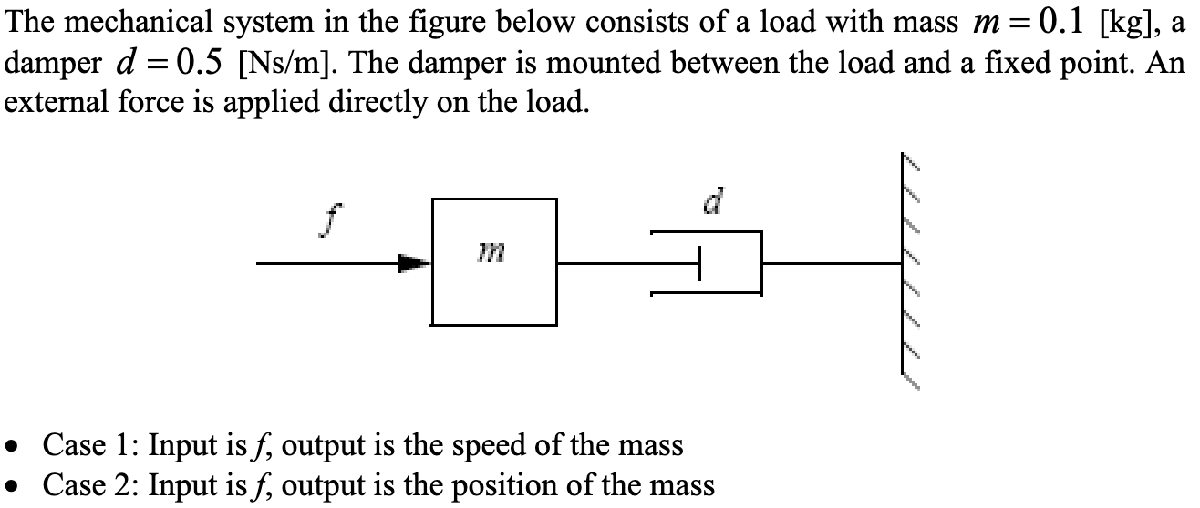

What is the order of the model if the input is f and the output is the speed of the mass?

In this case the system can be described by the formula: $m \dot{v} = f - dv
$ which can be rewritten as: $\dot{v} + \frac{d}{m} v = \frac{f}{m}
$. The highest derivative of the output here is the first derivative and therefore the model is of order 1.

If the output is the position of the mass, what is the order again?

In this case the system can be described by: $m \ddot{x} = f - d \dot{x}
$ which can be rewritten as: $\ddot{x} + \frac{d}{m} \dot{x} = \frac{f}{m}

$. The highest derivative of the output here is the second derivative and therefore the model is of order 2. 

The basic parameters of the system are given in the problem description

% Basic parameters definition
m = 0.1; % kg
d = 0.5; % Ns/m

The state space models and transfer functions were derived on paper according to the following: 

Case 1: 

State space model:


$$% Define the state-space matrices using brackets
A = [\frac{-d}{m}]\ % A matrix (1-by-1)
B = [\frac{1}{m}]\    % B matrix (1-by-1)
C = [1]\      % C matrix (1-by-1, output = v)
D = [0]\      % D matrix (1-by-1)
$$


Transfer function model: 


$$G_1(s) = \frac{1}{m s + d}
$$


% Derived state space model for case 1:

A = -d/m;

B = 1/m;

% u = F

C1 = 1;

D = 0;

sys1 = ss(A, B, C1, D);

% Derived transfer function model for velocity output

s = tf('s');

G1 = 1 / (m*s + d);

Case 2: 

State space model:


$$A = \left( \matrix{0 & 1 \cr 0 & -\frac{d}{m}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{m}} \right), \quad
C = \left( \matrix{1 & 0} \right), \quad
D = 0
$$


Transfer function model: 


$$G_2(s) = \frac{1}{m s^2 + d s}

$$


% Derived state space model for case 2:

A = [0, 1; 0, -d/m];

B = [0; 1/m];

C2 = [1, 0];

D = 0;

sys2 = ss(A, B, C2, D);

% Derived transfer function model for position output
G2 = 1 / (m*s^2 + d*s);

The frequency response (bode) for the models is shown below

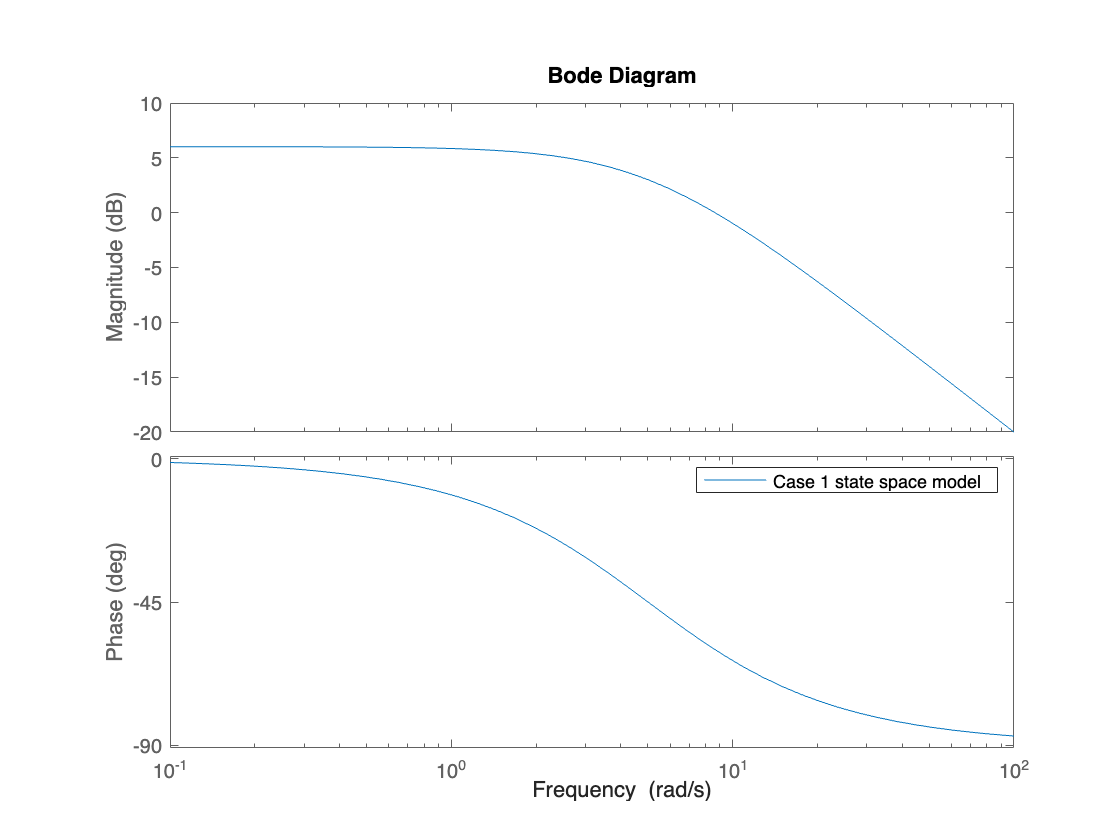

bode(sys1)
legend("Case 1 state space model")

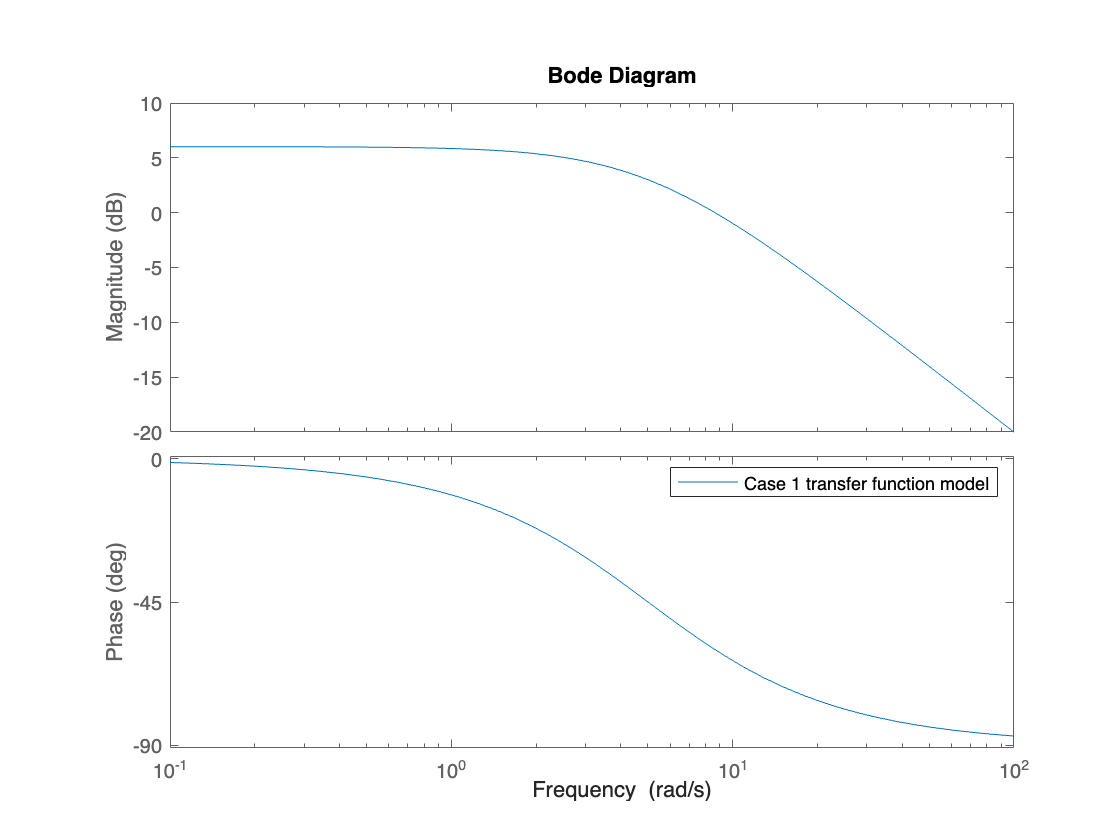


bode(G1)
legend("Case 1 transfer function model")

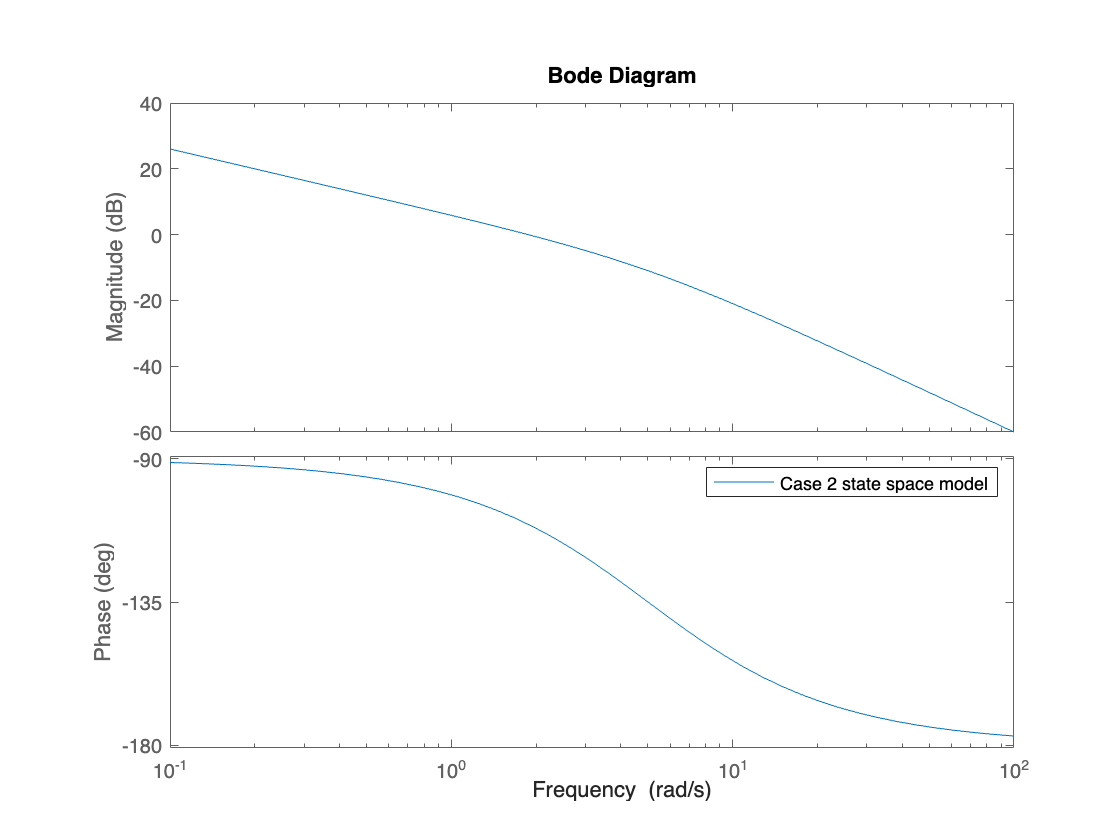


bode(sys2)
legend("Case 2 state space model")

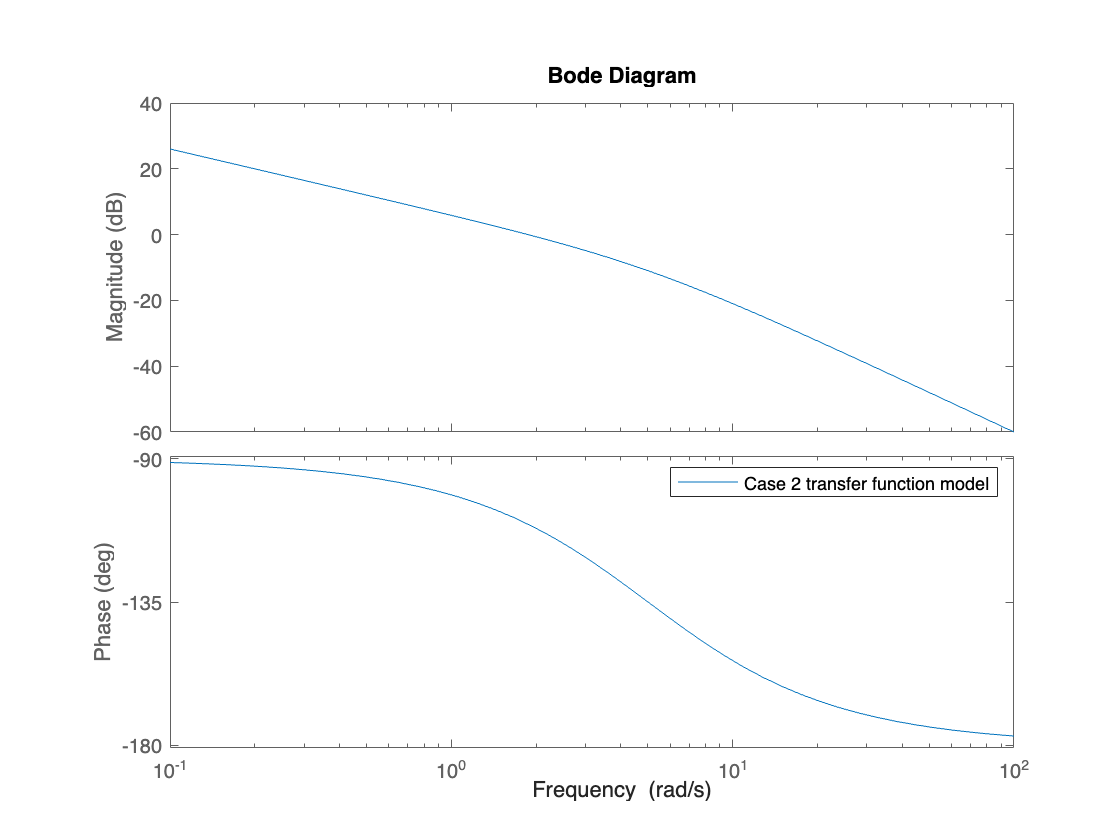


bode(G2)
legend("Case 2 transfer function model")

The step response of the systems are shown below

Step response of system with velocity as output:

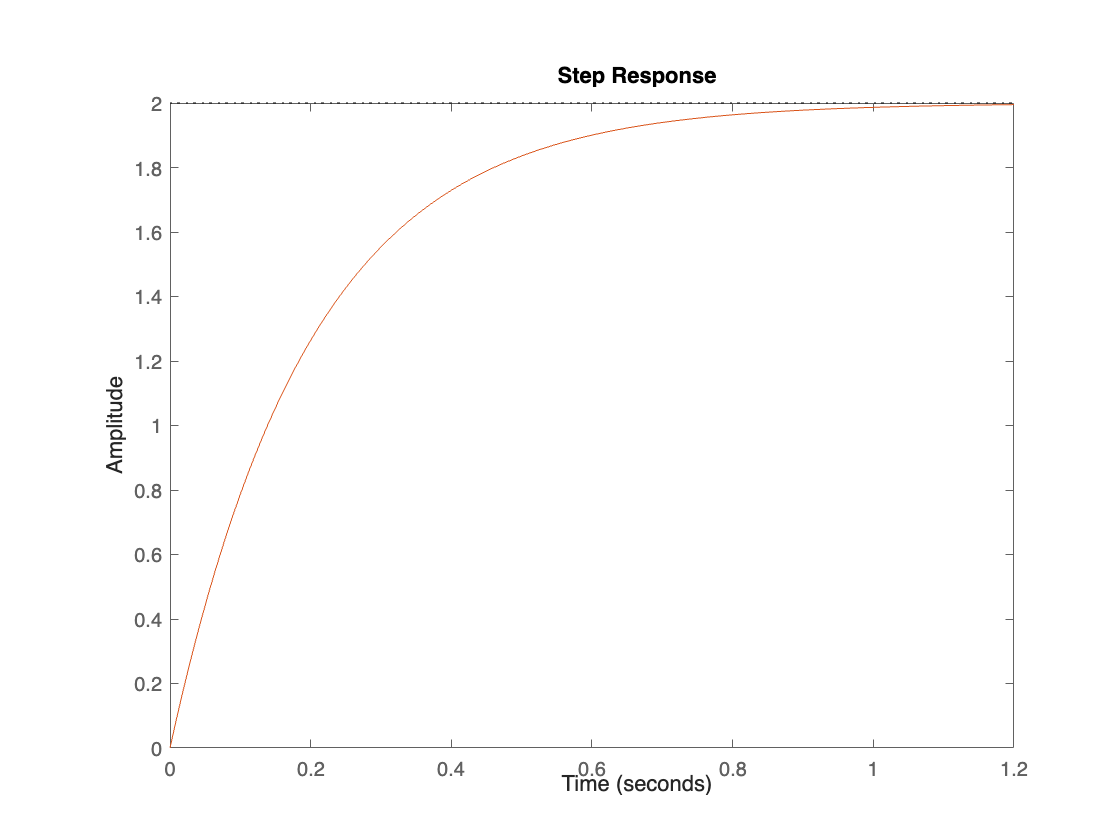


sp =

	resppack.timeplot



sp = stepplot(sys1, G1)

As can be seen in the graph, the amplitude of the velocity reaches a maximum at 2 m/s. This appears feasible. 

Step response of a system with position as output:

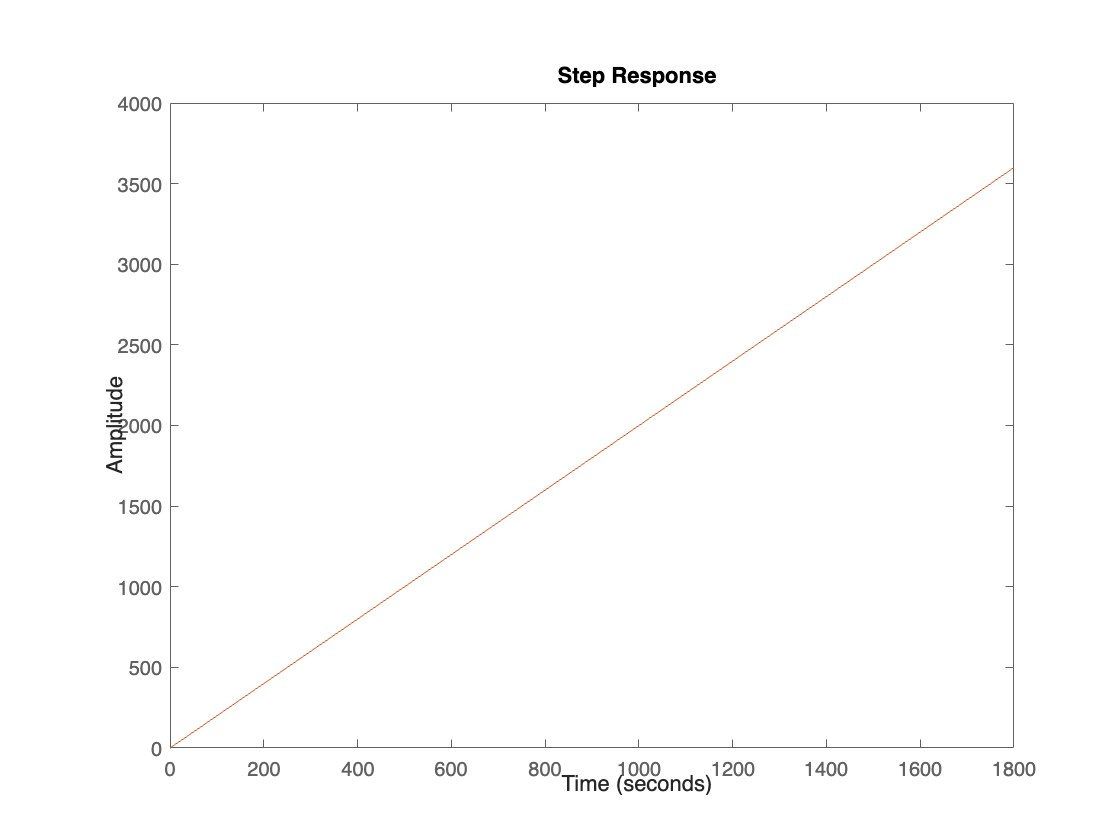


sp2 =

	resppack.timeplot



sp2 = stepplot(sys2, G2)

As can be seen in this graph, the output position magnitude keeps rising linearly. This also appears feasible given that we have a constant positive nonzero amplitude of the velocity after approximately 1,2s. If the velocity is always positive, the position will keep increasing unless some holonomic constraint prevents it from doing so. 

Furthermore the pole zero plots of the systems were graphed. 

Pole zero plot for system with velocity as output:

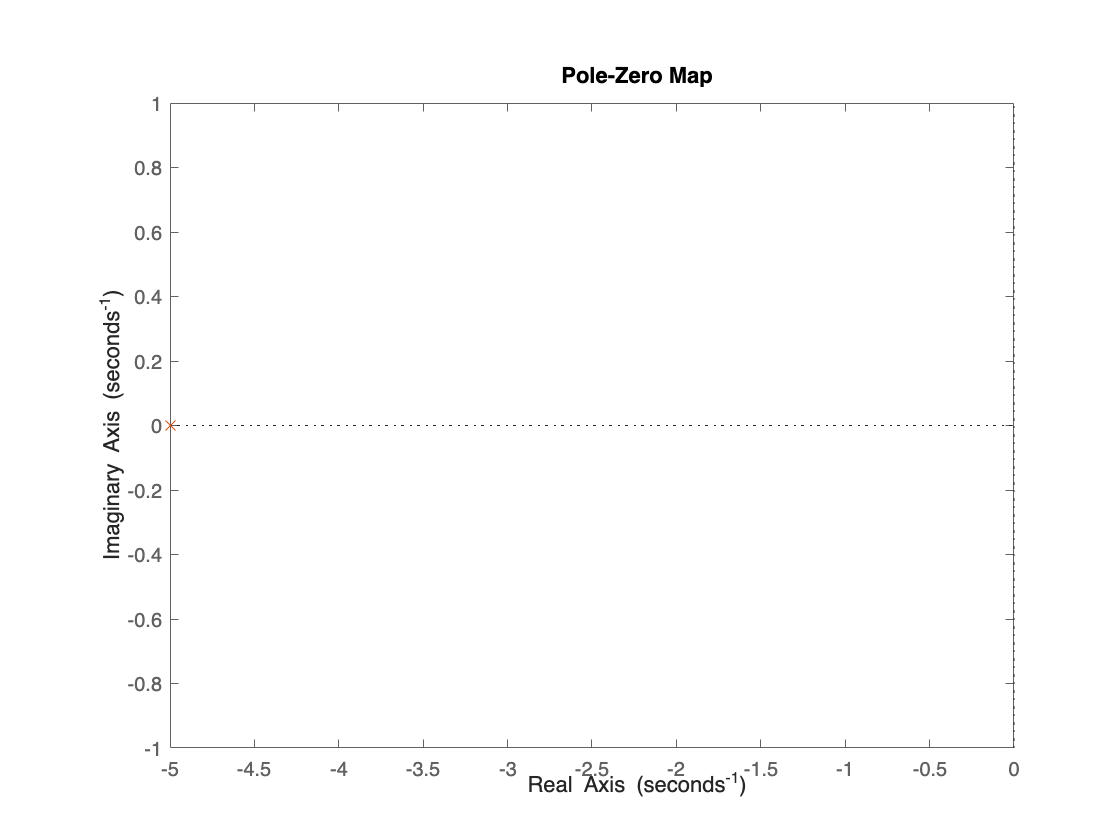


pzp =

	resppack.mpzplot



pzp = pzplot(sys1, G1)

As can be seen in the graph, the system has only one pole on the real axis at -5, and no zeroes. This is also what makes the step response converge to a value as time passes. 

The pole zsero plot of the system with position as output:

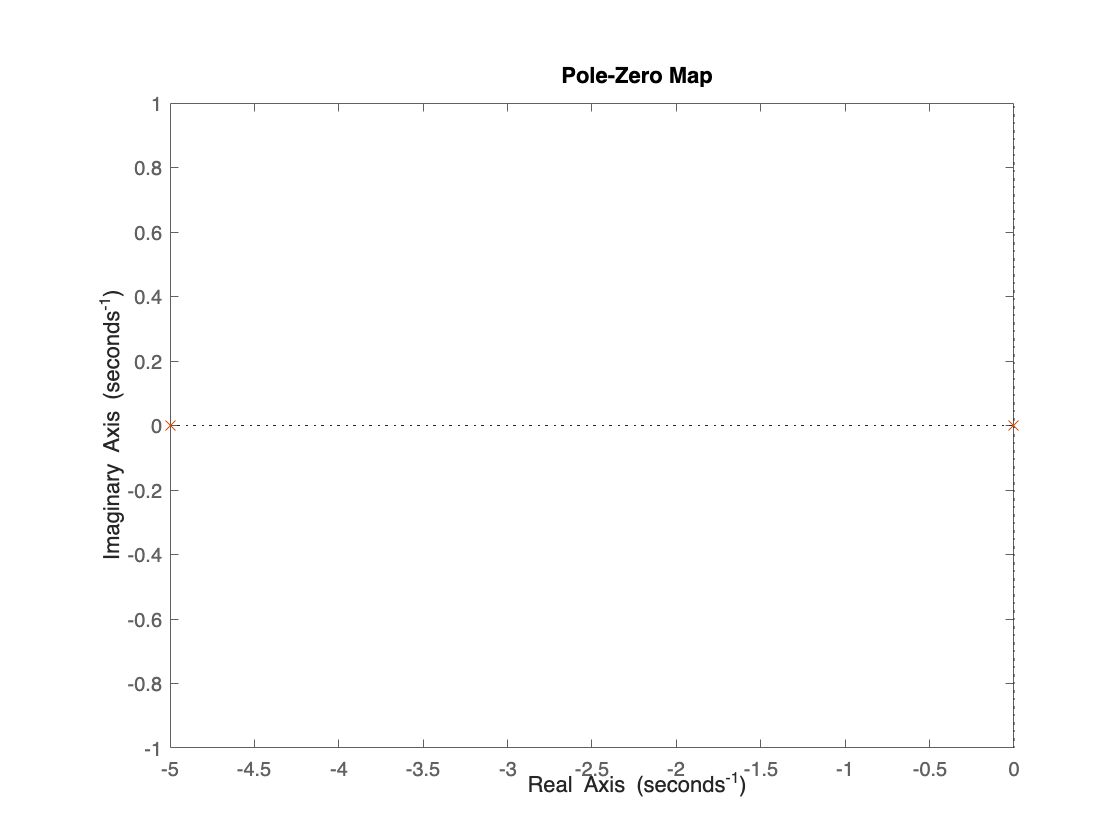


pzp2 =

	resppack.mpzplot



pzp2 = pzplot(sys2, G2)

As can be seen in this graph, the system has two poles, one at -5 and one at 0, the system has no zeroes. This shows that the system is marginally stable, and that in a continous time system the response of the system to a step input will not grow or decay, it will be a ramp. This is specifically the behavior shown in the step response plot for the system with position as output. 